**Mimic noise with high frequency harmonic oscilaltions**

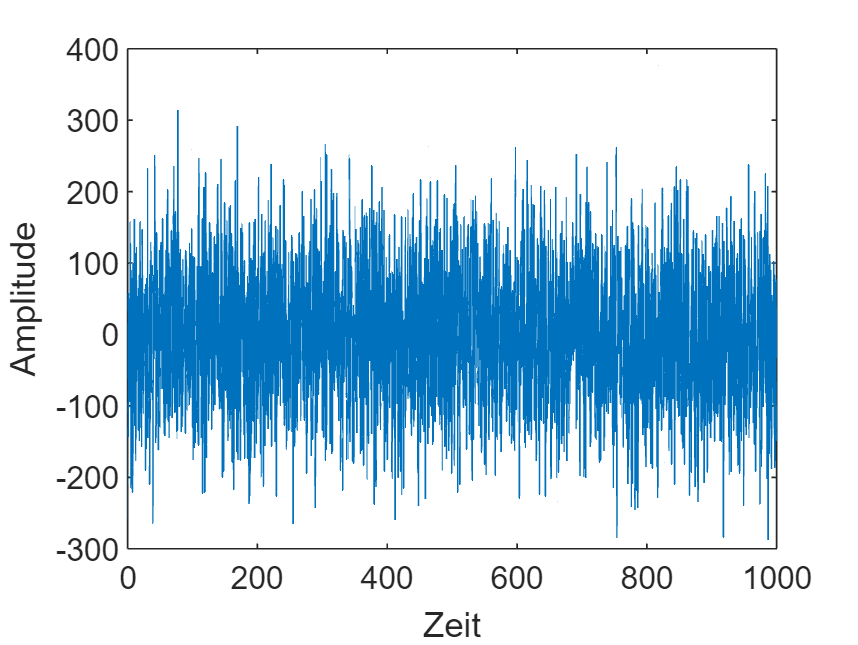

% Parameters for the simulation
num_oscillators = 13000;  % number of oscillators
t_end = 1000; % simulation end time
dt = 0.01; % time step size
t = 0:dt:t_end; % time vector

% Parameters for the oscillators
frequencies = randn(num_oscillators, 1); % frequencies of the oscillators
amplitudes = randn(num_oscillators, 1); % amplitudes of the oscillators
phases = 2*pi*rand(num_oscillators, 1); % phases of the oscillators

% Initialize the position vector
x = zeros(size(t));

% Calculate the position for each time point using all the oscillators
for i = 1:length(t)
    x(i) = sum(amplitudes .* cos(2*pi*frequencies*t(i) + phases));
end

figure
plot(t, x)
%title('"Rauschen" mittels überlagerten harmonischen Oszillatoren')
xlabel('Zeit')
ylabel('Amplitude')

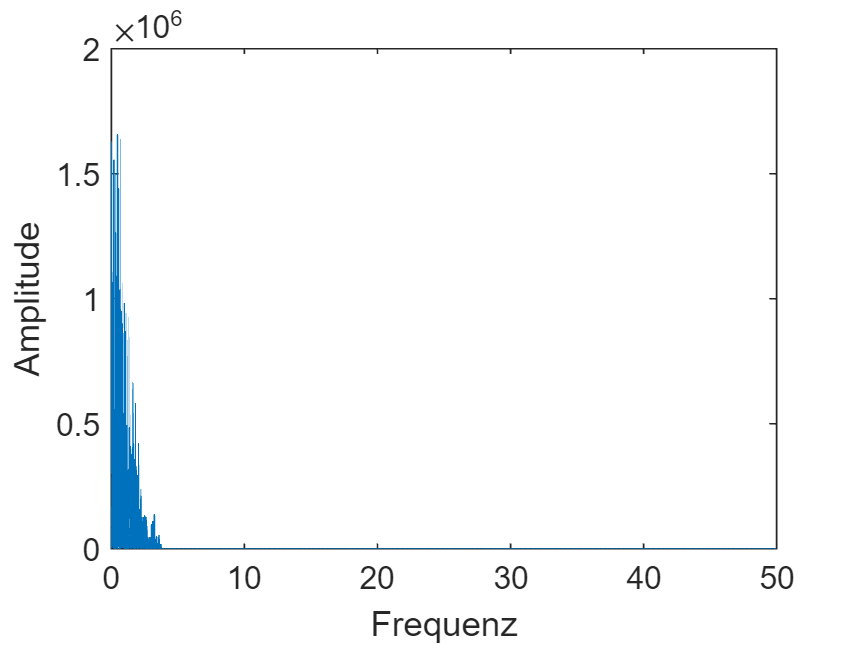


% Calculate the Fourier Transform of the signal
X = fft(x);

% Calculate the power spectrum (magnitude squared of each frequency component)
Pxx = abs(X).^2 / length(t);

% Frequency vector (considering only half the spectrum due to symmetry)
f = (0:(length(t)/2-1)) / (t_end); 

% Plot the power spectrum
figure
plot(f, Pxx(1:length(f)))
%title('FFT des harmonischen "Rausch-Signals"')
xlabel('Frequenz')
ylabel('Amplitude')

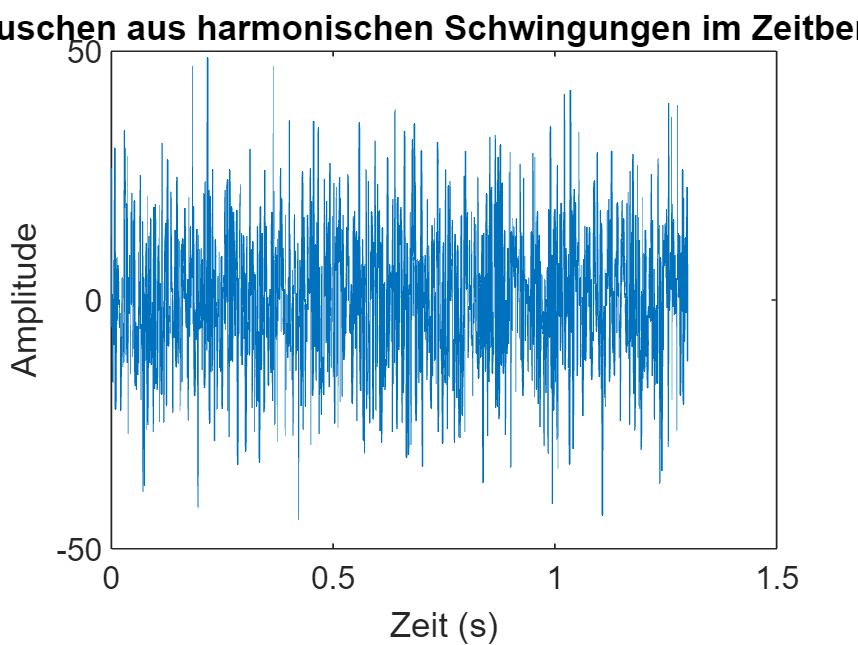

% Parameter
N = 1300; % Anzahl der Datenpunkte
Fs = 1000; % Abtastfrequenz in Hz
numHarmonics = 1300; % Anzahl der harmonischen Schwingungen

% Zeitachse erstellen
t = (0:N-1)/Fs;

% Rauschen durch Überlagerung harmonischer Schwingungen erzeugen
y = zeros(1, N);
for k = 1:numHarmonics
    freq = k * Fs/N; % Frequenz der harmonischen Schwingung
    phase = 2*pi*rand(); % Zufällige Phase zwischen 0 und 2*pi
    amp = rand(); % Zufällige Amplitude zwischen 0 und 1
    y = y + amp*sin(2*pi*freq*t + phase);
end

% Rauschen im Zeitbereich plotten
figure;
%subplot(2, 1, 1);
plot(t, y);
xlabel('Zeit (s)');
ylabel('Amplitude');
title('Rauschen aus harmonischen Schwingungen im Zeitbereich');

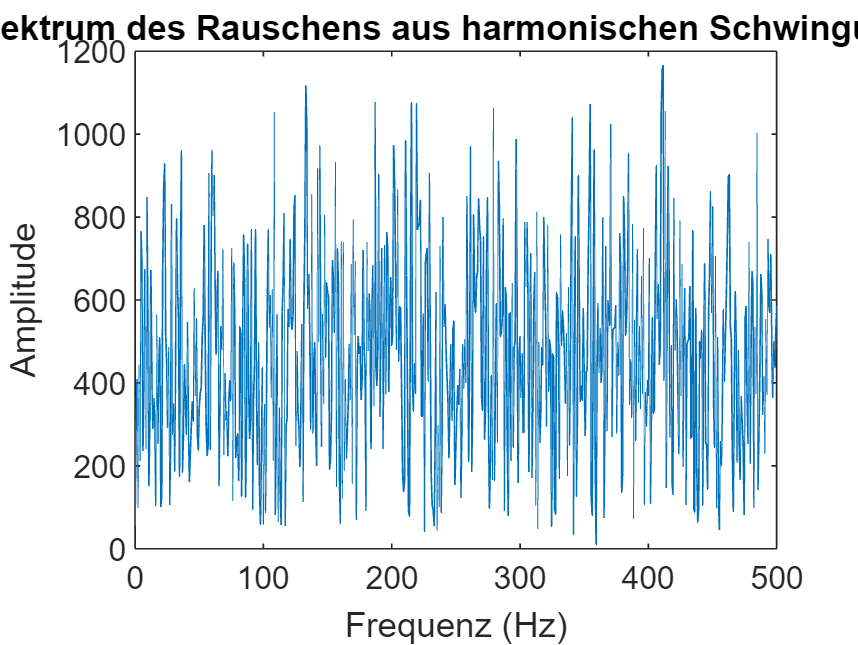


% FFT des Rauschens
Y = fft(y);

% Frequenzachse erstellen
f = (0:N-1) * Fs/N;

% Rauschen im Frequenzbereich plotten
figure;
%subplot(2, 1, 2);
plot(f, abs(Y));
xlabel('Frequenz (Hz)');
ylabel('Amplitude');
title('Spektrum des Rauschens aus harmonischen Schwingungen');
xlim([0 Fs/2]); % Zeigt nur positive Frequenzen

**Real Noise & Power Spectrum mittels wgn()**

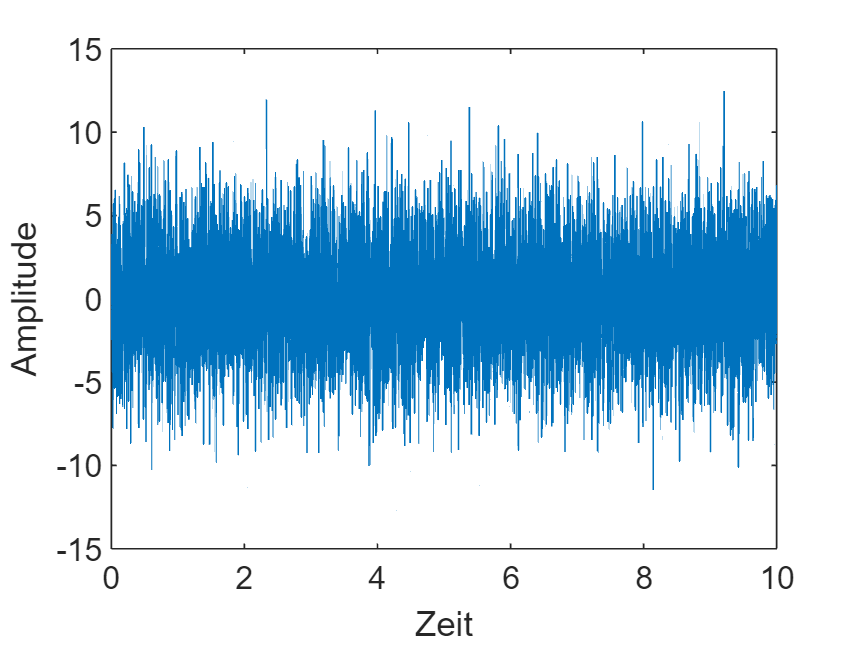

% Parameter für weißes Rauschen
N = 10000; % Anzahl der Datenpunkte
Fs = 1000; % Abtastfrequenz in Hz
SNR = 10; % Signal-Rausch-Verhältnis in dB

% Weißes Rauschen simulieren
y = wgn(N, 1, SNR);

% Zeitachse erstellen
t = (0:N-1)/Fs;

% Rauschen im Zeitbereich plotten
figure;
%subplot(2, 1, 1);
plot(t, y);
xlabel('Zeit');
ylabel('Amplitude');

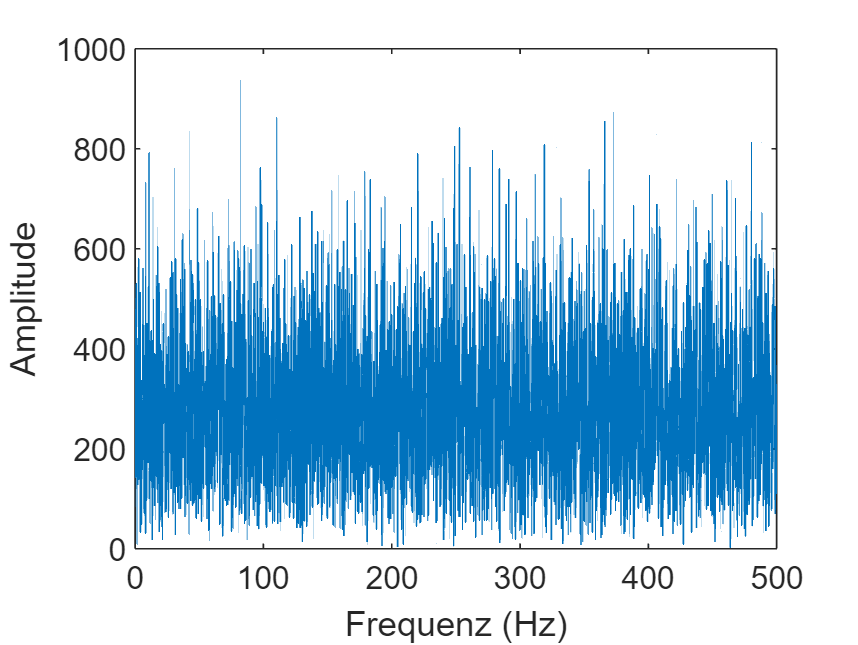

%title('Weißes Rauschen im Zeitbereich');

% FFT des Rauschens
Y = fft(y);

% Frequenzachse erstellen
f = (0:N-1) * Fs/N;

% % Rauschen im Frequenzbereich plotten
% figure;
% %subplot(2, 1, 2);
% plot(f, 10*log10(abs(Y).^2));
% xlabel('Frequenz');
% ylabel('Leistungsdichte (dB/Hz)');
% %title('Spektrum des weißen Rauschens');
% xlim([0 Fs/2]); % Zeigt nur positive Frequenzen

figure;
plot(f, abs(Y));
xlabel('Frequenz (Hz)');
ylabel('Amplitude');
%title('Spektrum des weißen Rauschens');
xlim([0 Fs/2]); % Zeigt nur positive Frequenzen

**Real Noise & Power Spectrum mittels randn()**

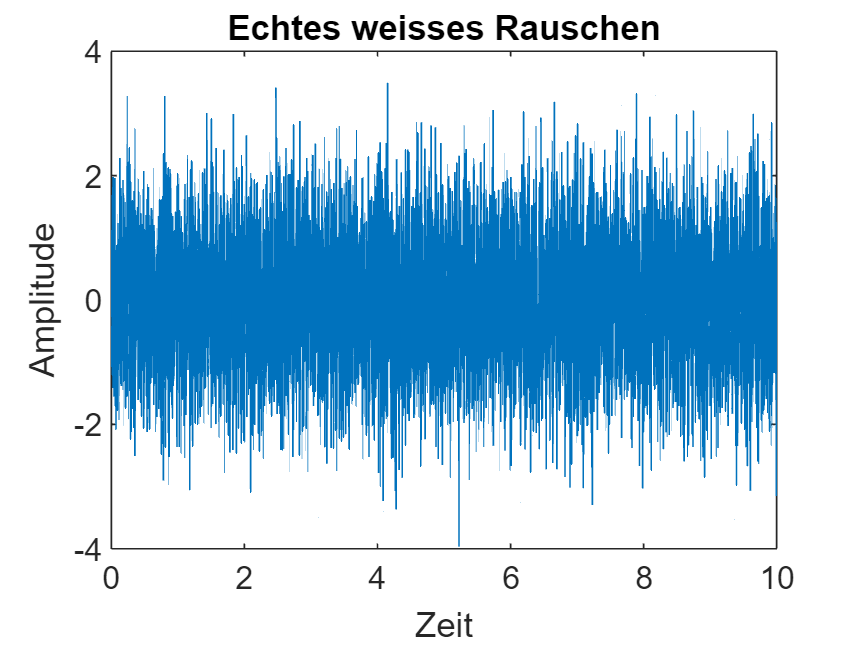

% Parameters
N = 10000;  % Number of samples
fs = 1000;  % Sampling rate in Hz
T = N/fs;   % Total time
t = (0:N-1)/fs;  % Time vector

% Generate white noise
noise = randn(1, N);

% Plot the noise signal
figure(1);
plot(t, noise);
xlabel('Zeit');
ylabel('Amplitude');
title('Echtes weisses Rauschen');

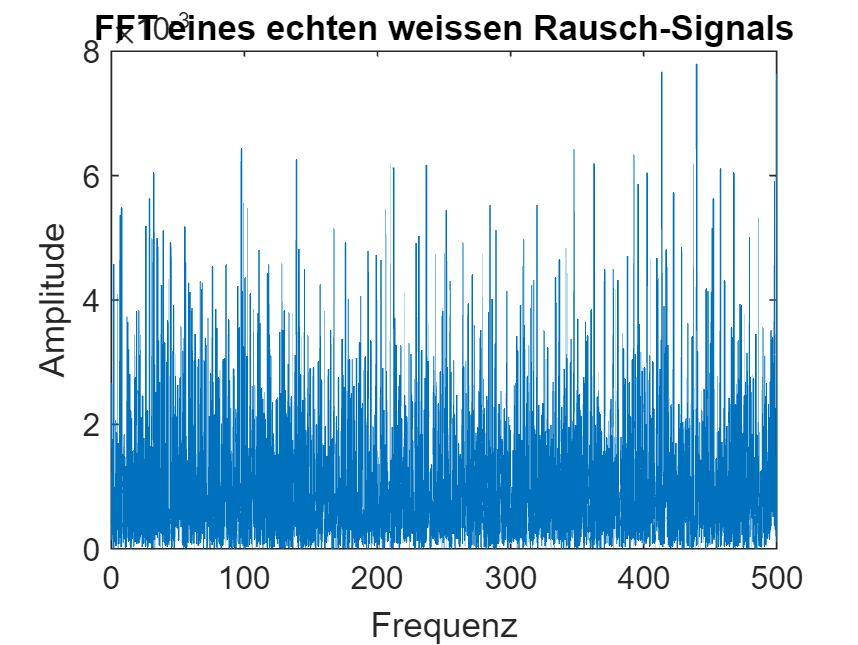

%title('White Noise (N=10000, f=1000)');

% Compute the Fourier transform
f_noise = fft(noise);

% Compute the power spectrum
Pxx = (1/(fs*N)) * abs(f_noise).^2;

% Frequency vector
f = 0:fs/N:fs/2;

% Plot the power spectrum
figure(2);
plot(f, Pxx(1:length(f)));
xlabel('Frequenz');
ylabel('Amplitude');
title('FFT eines echten weissen Rausch-Signals');


% Show that power spectral density is approximately constant
mean_Pxx = mean(Pxx(1:length(f)));
disp(['Mean power spectral density: ', num2str(mean_Pxx)]);

Mean power spectral density: 0.0010057
